# Tree Carbon Intake Modeling

## Model Parameters

mtype = "stofeed" ;% Model type
Nt = 1000;% Number of trees in a patch
r =0.5;% Mean growth rate
TB = 0.002;% Total biomass of 1 tree
WP = 0.3;% Percentage of water in total tree biomass
CP =0.5;% Percentage of carbon in dry biomass
t = 36;% Number of years
%########################################################################%
std = 0.1;% Standard Deviation for stochastic 
% growth model
%########################################################################%
maxr =0.67;% Max growth rate for growth feedback
maxbio = 0.075;% Max biomass for growth feedback

## Variables

DB = TB-(TB*WP);% Dry Biomass of a tree
C = DB*CP; % Total Carbon in a tree
%disp("Total carbon in a tree is "+C)
CpP = C*Nt;
%disp("Carbon per patch in a year is "+CpP)
Total_biomass = TB*Nt;
Dry_biomass = DB*Nt;

%Make the "storage variables"
generation = linspace(0,t,t+1);
growth = zeros(size(generation));
carbon = zeros(size(generation));
biomass = zeros(size(generation));
drybio = zeros(size(generation));

## Run Model

%"If" statement selects appropriate model
if mtype == "constant"   %run the constant growth model
    for i = 1:size(generation,2)    
        if i == 1   %The generation has population = N0
            carbon(i) = CpP;
            growth(i) = 0;
            biomass(i) = Total_biomass;
            drybio(i) = Dry_biomass;
        else
            growth(i) = r;
            carbon(i) = carbon(i-1)+(carbon(i-1)*growth(i)); %At the new
            %timestep, the population has grown by dNdt from the previous
            %generation
            biomass(i) = biomass(i-1)+(biomass(i-1)*growth(i));
            drybio(i) = drybio(i-1)+(drybio(i-1)*growth(i));
        end
    end
    
elseif mtype == "stochastic"   %run the stochastic growth model
    for i = 1:size(generation,2)
        if i == 1
            growth(i) = 0;
            carbon(i) = CpP;
            biomass(i) = Total_biomass;
            drybio(i) = Dry_biomass;
        else
            growth(i) = [norminv(rand(),r,std)];
            carbon(i) = carbon(i-1)+(carbon(i-1)*growth(i));
            biomass(i) = biomass(i-1)+(biomass(i-1)*growth(i));
            drybio(i) = drybio(i-1)+(drybio(i-1)*growth(i));
        end
    end
elseif mtype == "feedback"   %run the growth feed back model
    for i = 1:size(generation,2)
        if i == 1
            carbon(i) = CpP;
            biomass(i) = Total_biomass;
            growth(i) = 0;
            drybio(i) = Dry_biomass;
        else
            growth(i) = (maxr*((maxbio-(biomass(i-1)/Nt))/maxbio));
            carbon(i) = carbon(i-1)+(carbon(i-1)*growth(i));
            biomass(i) = biomass(i-1)+(biomass(i-1)*growth(i));
            drybio(i) = drybio(i-1)+(drybio(i-1)*growth(i));
        end
    end
elseif mtype == "stofeed"   %run the stochastic + feedback model
    for i = 1:size(generation,2)
        if i == 1
            carbon(i) = CpP;
            biomass(i) = Total_biomass;
            growth(i) = 0;
            drybio(i) = Dry_biomass;
        else
            for m = 1:10
    % Generate a random number that must be lower than a certain value
            random_value = norminv(rand(), r, std);
                while random_value >= maxr % Replace 'some_value' with your threshold
                random_value = norminv(rand(), r, std);
                end
                growth(i) = random_value*((maxbio-(biomass(i-1)/Nt))/maxbio);
            end
            %growth(i) = ((norminv(rand(),r,std))*((maxbio-(biomass(i-1)/Nt))/maxbio));
            carbon(i) = carbon(i-1)+(carbon(i-1)*growth(i));
            biomass(i) = biomass(i-1)+(biomass(i-1)*growth(i));
            drybio(i) = drybio(i-1)+(drybio(i-1)*growth(i));
        end
    end
end

## Visualize result

% Create a table
Carbon_T = table(generation', carbon', growth', biomass', drybio', ...
    'VariableNames', {'Year', 'Carbon', 'Yearly growth rate', 'Total Biomass', ...
    ['Dry Biomass']});

% Display the table
disp(Carbon_T);

    Year    Carbon     Yearly growth rate    Total Biomass    Dry Biomass
    ____    _______    __________________    _____________    ___________

      0         0.7                 0                2             1.4   
      1     0.97798           0.39711           2.7942           1.956   
      2      1.4046           0.43624           4.0132          2.8092   
      3      2.1715           0.54595           6.2042          4.3429   
      4      3.1764           0.46279           9.0754          6.3528   
      5      4.3606           0.37282           12.459          8.7212   
      6      5.0703           0.16276           14.487          10.141   
      7      7.3564           0.45087           21.018          14.713   
      8      10.387             0.412           29.678          20.774   
      9      13

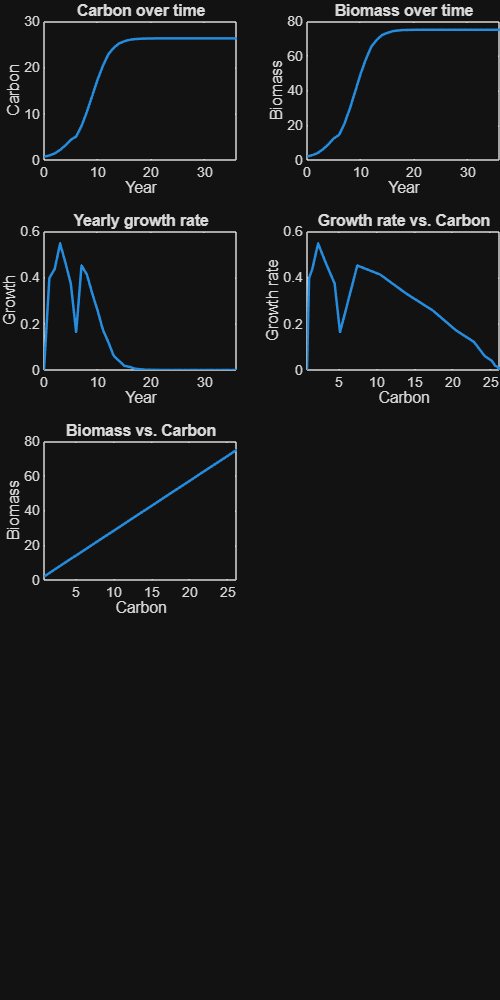


%Make a plot to look at your results
figure('Position',[50 50 400 800]);
tiledlayout(5,2,'Padding','tight')

nexttile
plot(generation,carbon,'LineWidth',1.5)
xlabel('Year')
ylabel('Carbon')
title('Carbon over time')
xlim([min(generation) max(generation)])

nexttile
plot(generation,biomass,'LineWidth',1.5)
xlabel('Year')
ylabel('Biomass')
title('Biomass over time')
xlim([min(generation) max(generation)])

nexttile
plot(generation,growth,'LineWidth',1.5) 
xlabel('Year')
ylabel('Growth')
title('Yearly growth rate')
xlim([min(generation) max(generation)])

nexttile
plot(carbon,growth,'LineWidth',1.5) 
xlabel('Carbon')
ylabel('Growth rate')
title('Growth rate vs. Carbon')
xlim([min(carbon) max(carbon)])

nexttile
plot(carbon,biomass,'LineWidth',1.5) 
xlabel('Carbon')
ylabel('Biomass')
title('Biomass vs. Carbon')
xlim([min(carbon) max(carbon)])